# MECH 6323 - Homework 2

Author: Jonas Wanger

Date: 2022-02-13

## Problem 3

% 2nd TF
H1 = zpk(-1000,[],1/10);
H2 = tf([1/1], [1 2*(1/10)*1 1^2]);
H3 = tf([1/(10^2)], [1 2*(1/10)*10 (10)^2]);
H = H1 * H2 * H3

H =
 
           0.001 (s+1000)
  ---------------------------------
  (s^2 + 0.2s + 1) (s^2 + 2s + 100)
 
Continuous-time zero/pole/gain model.



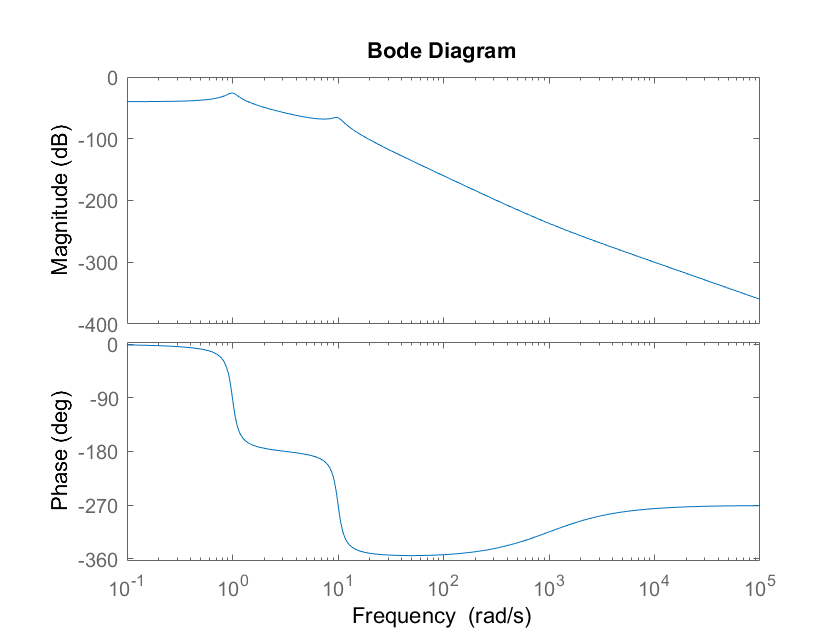


bode(H)

## Problem 4

C = zpk(-3,0,10)

C =
 
  10 (s+3)
  --------
     s
 
Continuous-time zero/pole/gain model.



P1 = zpk([],[3],-0.5);
P2 = tf([1 0 -2000],[1 50 1000]);
P = P1 * P2

P =
 
     -0.5 (s^2 + 2000)
  ------------------------
  (s+3) (s^2 + 50s + 1000)
 
Continuous-time zero/pole/gain model.




% Part a
H = feedback(C*P,-1)

H =
 
          -5 (s+3) (s^2 + 2000)
  --------------------------------------
  (s+3) (s+34.37) (s^2 + 20.63s + 290.9)
 
Continuous-time zero/pole/gain model.



isstable(H)

ans = logical
   1



% Part b
L = C*P

L =
 
    -5 (s+3) (s^2 + 2000)
  --------------------------
  s (s+3) (s^2 + 50s + 1000)
 
Continuous-time zero/pole/gain model.



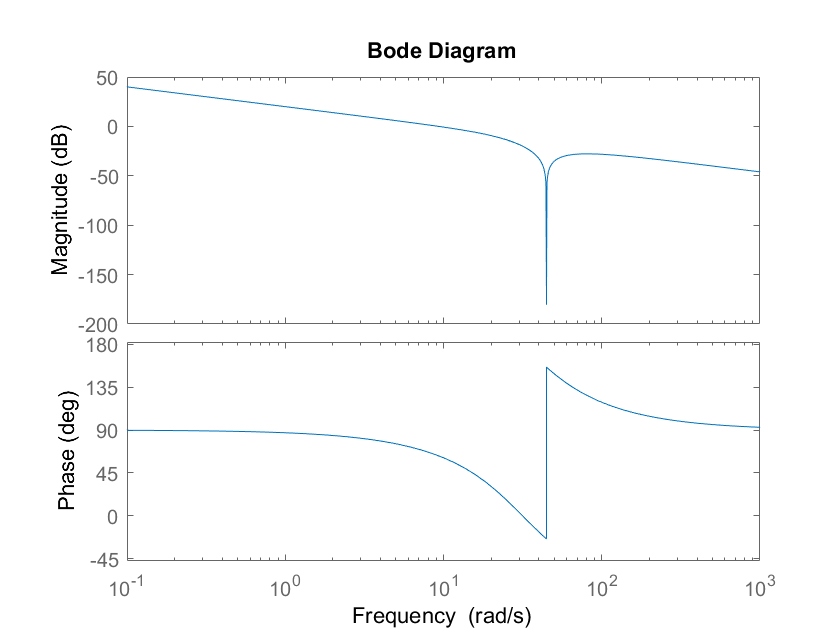

bode(L)

allmargin(L)

ans = struct with fields:
     GainMargin: [1×0 double]
    GMFrequency: [1×0 double]
    PhaseMargin: -117.0643
    PMFrequency: 9.3294
    DelayMargin: 0.4545
    DMFrequency: 9.3294
         Stable: 0



% Part c
